clear;
clc;close all;

addpath('./flann/');

s=10;
gridStep=0.3;
scale_detect_gridstep=1;
max_scale_detect_size=300;
overlap=0.5;
icpSteps=200;
TrMin=0.5;
TrMax=0.9;
%尺度平衡子（让待配准的两幅图比例保持又不过多影响gridstep）
zoomVar=1;
downStep=0.03;

## 转灰度

map1=rgb2gray(imread('D:\workspaceMatlab\grid_map_regis_project\map_different_scale\Fr79a1_2.png'));
map2=rgb2gray(imread('D:\workspaceMatlab\grid_map_regis_project\map_different_scale\Fr79a2_6.png'));
% im1 = imread('D:\workspaceMatlab\grid_map_regis_project\map_different_scale\Fr79a1_2.png');
% im2 = imread('D:\workspaceMatlab\grid_map_regis_project\map_different_scale\Fr79a2_5.png'); 
% im1 = imread('..\map_data\pair2\Intel1_1_1000_40.png');
% im2 = imread('..\map_data\pair2\2.png'); 

% imshowpair(map1,map2);
tic;


harris点 

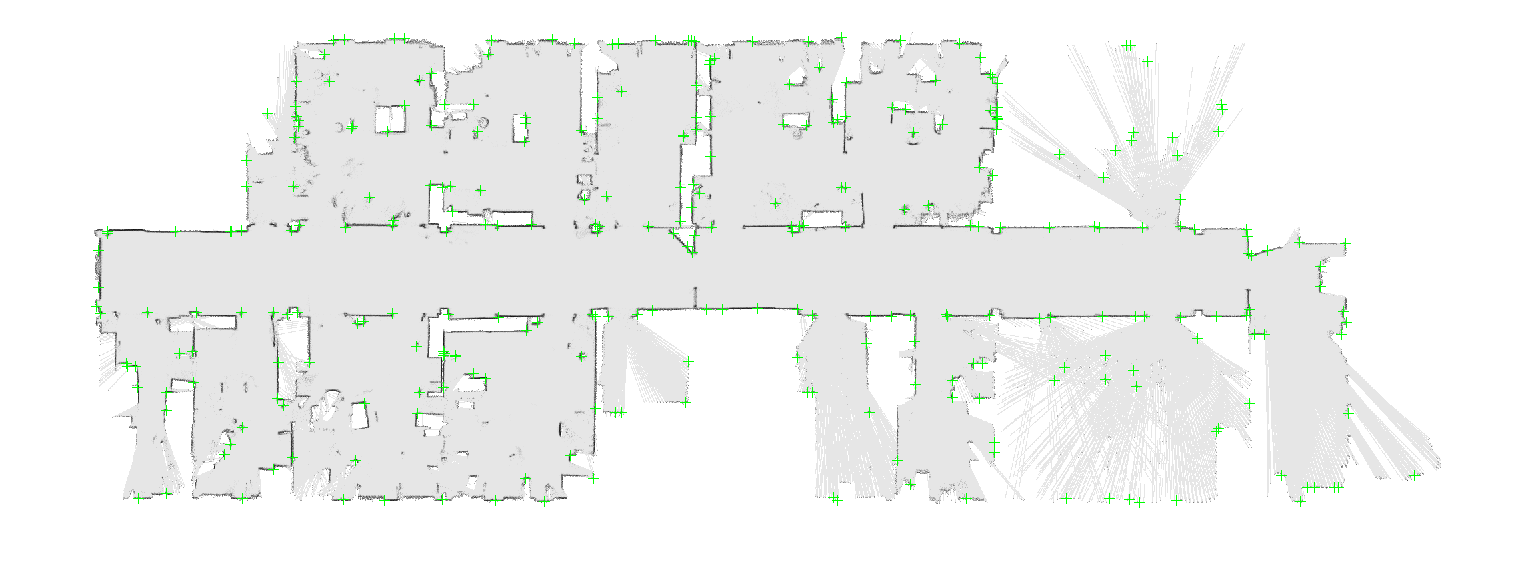

figure
imshow(map1);hold on
corner_Point1 = detectHarrisFeatures(map1);
sele_corner_points1 =corner_Point1.selectUniform(300,size(map1));
plot(sele_corner_points1);

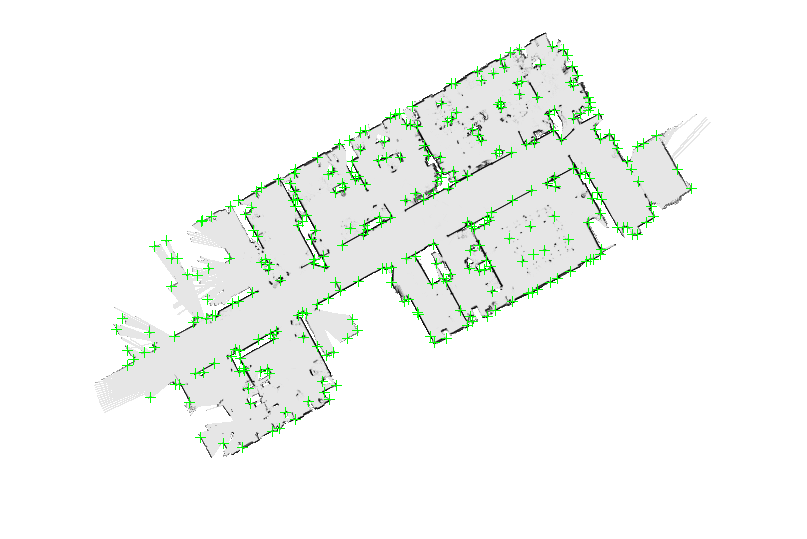

%% 灰度角点
% % figure
% % imshow(map1);hold on
% % gray1 = edge(map1);
% % corner_Point2 = detectHarrisFeatures(gray1);
% % plot(corner_Point2.selectUniform(300,size(map1)));
% cornersM1=SURFPoints(result(1:2,sele)','Scale',result(3,sele));

figure
imshow(map2);hold on
corner_Point2 = detectHarrisFeatures(map2);
sele_corner_points2 =corner_Point2.selectUniform(300,size(map2));
plot(sele_corner_points2);

#### 提取二维点云

[~,pointCMap1]=exarctPCfroImg(map1);
[~,pointCMap2]=exarctPCfroImg(map2);

#### 尺度检测

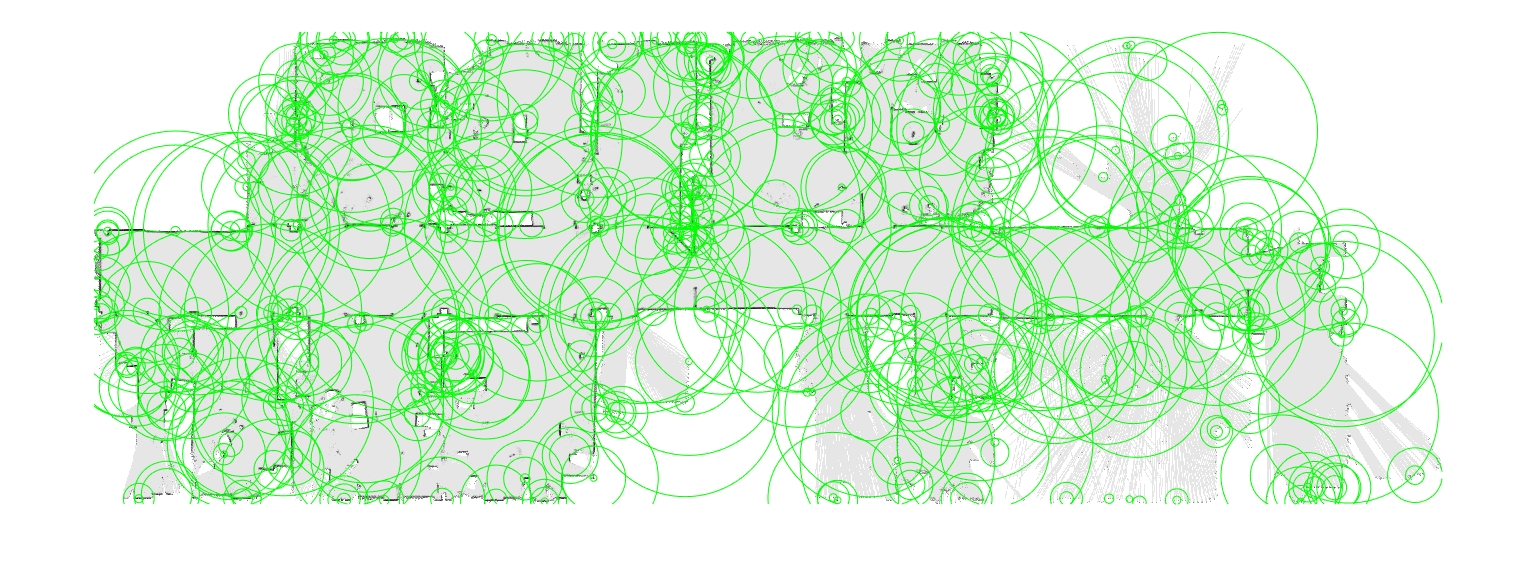

% 2.均匀分布选取harris角点最强点200个    (current) 
figure;
imshow(map1);hold on;
points_scale1 = detectScale(pointCMap1,sele_corner_points1.Location,scale_detect_gridstep,max_scale_detect_size);
draw_circle(points_scale1.Location,points_scale1.ScaleRadius);

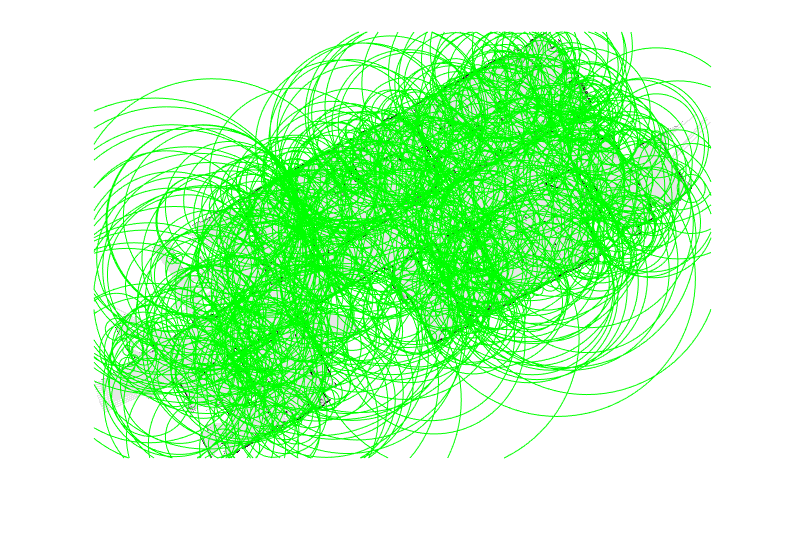

% 
figure;
imshow(map2);hold on;
points_scale2 = detectScale(pointCMap2,sele_corner_points2.Location,scale_detect_gridstep,max_scale_detect_size);
draw_circle(points_scale2.Location,points_scale2.ScaleRadius);

% 

存储尺度点（加缩放）

zSeleCorM1=HarrisGridPoints(points_scale1.Location/s,points_scale1.ScaleRadius/s);
zSeleCorM2=HarrisGridPoints(points_scale2.Location/s,points_scale2.ScaleRadius/s);


### 点云整体缩放s

pointCMap1=pointCMap1/s;
pointCMap2=pointCMap2/s;


### 基于尺度获取描述子

[M1Desp,M1Scale,M1Seed,M1Norm]=exarctEIG2d(pointCMap1,gridStep,zSeleCorM1,zoomVar); 
[M2Desp,M2Scale,M2Seed,M2Norm]=exarctEIG2d(pointCMap2,gridStep,zSeleCorM2,zoomVar); 


## 匹配

Motion=eigMatch2D(M1Desp,M2Desp,M1Scale,M2Scale,M1Seed,M2Seed,M1Norm,M2Norm,overlap,gridStep,map1,map2,s);

## 修正尺度 

s=SQRT((S*COS(THETA))^2+(S*SIN(THETA))^2)

%%根据相似变换和比例公式推倒缩放因子
scaleC=sqrt(sum(Motion(1:2,1).^2))

scaleC = single
0.3252

map1 = imresize(map1,scaleC);
corner_Point1 = detectHarrisFeatures(map1);
sele_corner_points1 =corner_Point1.selectUniform(300,size(map1));
[pcMap3d1,pointCMap1]=exarctPCfroImg(map1);
points_scale1 = detectScale(pointCMap1,sele_corner_points1.Location,scale_detect_gridstep,max_scale_detect_size);
zSeleCorM1=HarrisGridPoints(points_scale1.Location/s,points_scale1.ScaleRadius/s);
pointCMap1=pointCMap1/s;
[M1Desp,M1Scale,M1Seed,M1Norm]=exarctEIG2d(pointCMap1,gridStep,zSeleCorM1,zoomVar); 
Motion=eigMatch2D(M1Desp,M2Desp,M1Scale,M2Scale,M1Seed,M2Seed,M1Norm,M2Norm,overlap,gridStep,map1,map2,s);
scaleC=sqrt(sum(Motion(1:2,1).^2));

ICP

pointCMap1Scaled = pointCMap1*scaleC;
pointCMap1ScaledDown = pcdownsample2d(pointCMap1Scaled,downStep);
pointCMap2ScaledDown = pcdownsample2d(pointCMap2,downStep);
% pointCMap1ScaledDown = pcdownsample2d(pointCMap1,downStep);
% pointCMap2ScaledDown = pcdownsample2d(pointCMap2,downStep);
R0=Motion(1:2,1:2);
t0=Motion(1:2,3);
% opMotion=Motion;
R0=R0./scaleC;%成为刚体变换以ICP
[s, R, t, TriKSIB, minPhi] = FastTrICP(pointCMap2ScaledDown',pointCMap1ScaledDown',1,R0,t0,icpSteps,TrMin,TrMax);
% [R,t,~,minPhi]=fastTrICP2D(pointCMap2ScaledDown',pointCMap1ScaledDown',R0,t0,TrMin,TrMax,icpSteps);
minPhi

minPhi = single
0.0131

opMotion=[R.*s,t;0 0 1];
toc

历时 16.997482 秒。


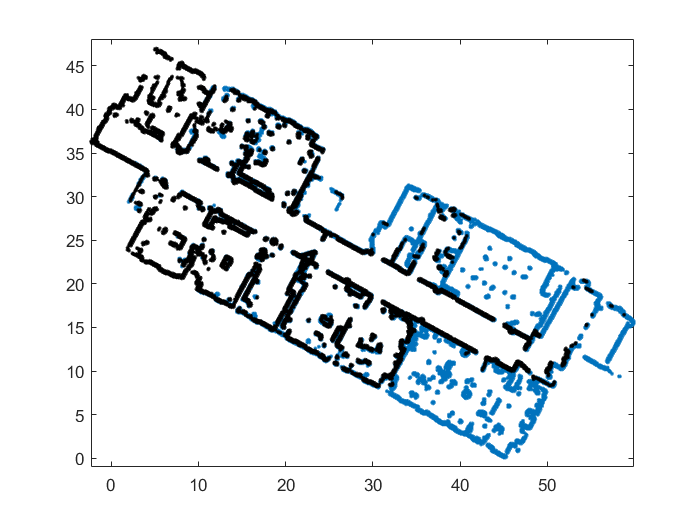

figure;
obtain2d(pointCMap2ScaledDown,'.');hold on;
transMap=opMotion*[pointCMap1ScaledDown';ones(1,length(pointCMap1ScaledDown))];
obtain2d(transMap,'.k');

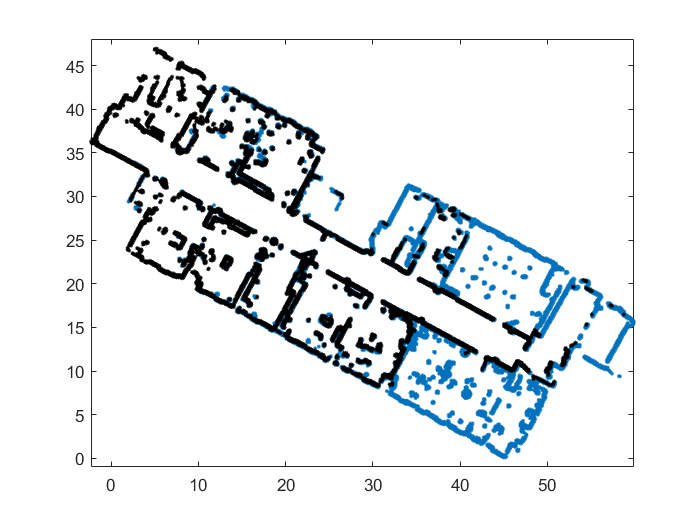


figure;
obtain2d(pointCMap2ScaledDown,'.');hold on;
transMap=[[R0,t0];[0,0,1]]*[pointCMap1ScaledDown';ones(1,length(pointCMap1ScaledDown))];
obtain2d(transMap,'.k');


% obtain2d(zSeleCorM2.Location,'+r');
% transFeaPoint=opMotion*[zSeleCorM1.Location';ones(1,length(zSeleCorM1.Location))];
% obtain2d(transFeaPoint,'xm');
% pcshow(pcMap3d2);hold on;
% pcshow(pctransform(pcMap3d1,affine3d(Motion')));
% imshow(imrotate(map1,74.0));
% imshowpair(map1,map2);
% imshow(imresize(map1,[200,200]));